Potenziale elicoidale

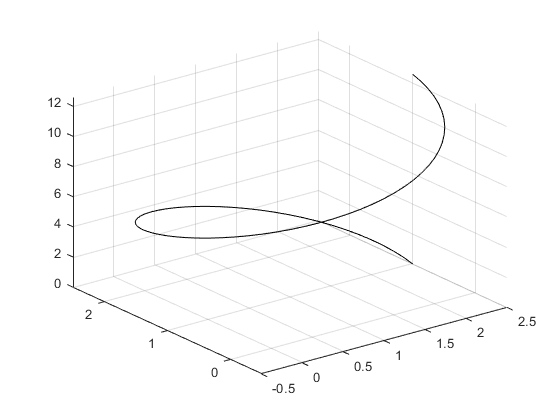

clearvars
syms u v r t;
r = v; t = u;
x0 = 1; y0 = 1;
c = 2;

%Forma parametrica
x = x0 + 1.5*cos(t);
y = [y0 + 1.5*sin(t)]';
z = c*t;

%Plot
fsurf(x,y,z,[0 2*pi]);

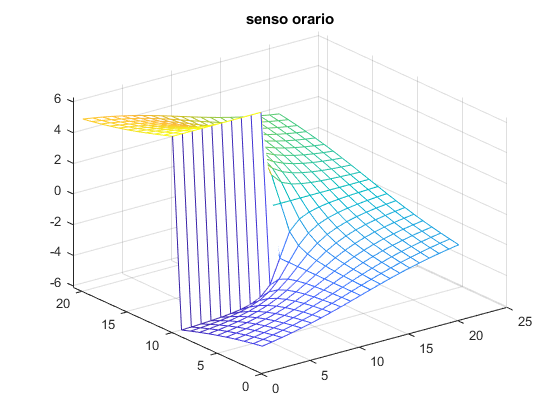

% x = 2; y = 2;
% syms x y;
x = 0:0.1:2; y = [0:0.1:2]';
pot1 = c*atan2(y-y0,x-x0);
mesh(pot1); title("senso orario");

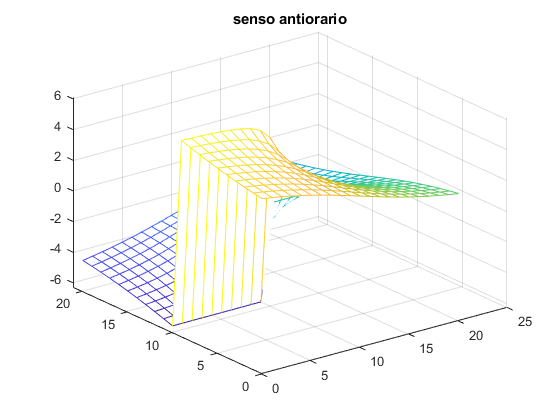

pot2 = -c * atan2(y-y0,x-x0);
mesh(pot2); title("senso antiorario");

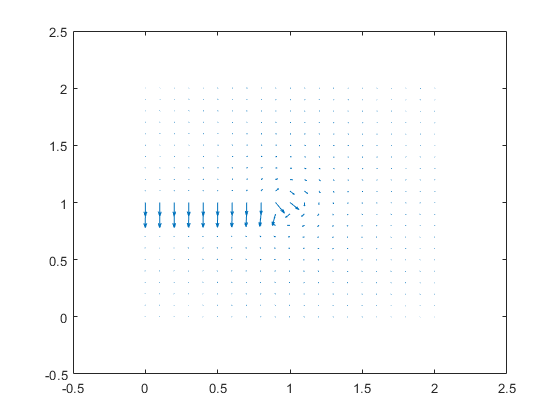

[X,Y] = meshgrid(0:0.1:2,0:0.1:2);
[gx1,gy1] = gradient(pot2);

gx = c*(y-y0)./((x-x0).^2+(y-y0).^2);
gy = c*(x0-x)./((x-x0).^2+(y-y0).^2);

figure;
quiver(X,Y,gx1,gy1);

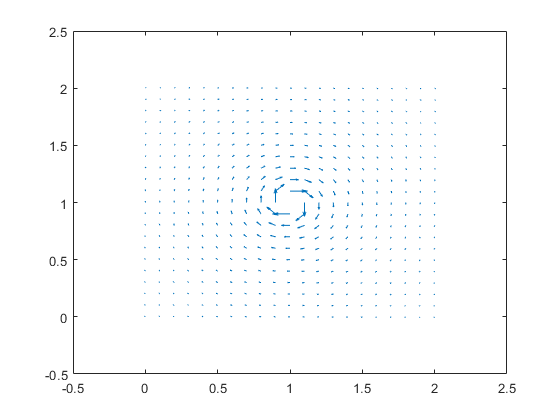

figure; x = 0:0.1:2; y = [0:0.1:2]';
quiver(X,Y,gx,gy);

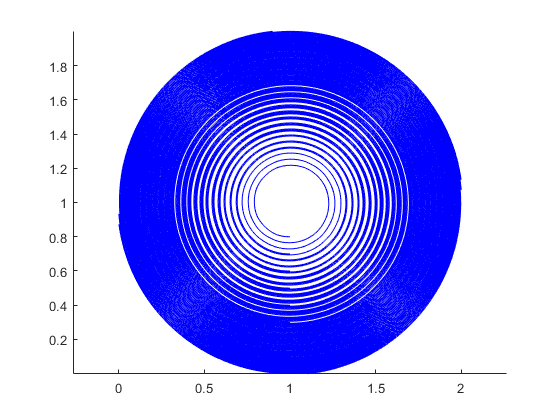

starty = 0.1:0.1:1;
startx = ones(size(starty));
figure;
streamline(X,Y,gx,gy,startx,starty);
axis equal